## Actual Script below

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

% Take first file (that covers 12 hours already)
trace_location = "../../traces/alibaba/2022-ms/NodeMetrics/NodeMetricsUpdate_0.csv";
[trace_header, trace_formats, trace_vartypes] = constants();
ds = tabularTextDatastore(trace_location, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedVariableNames",trace_header, ...
    "SelectedFormats", trace_formats);

clear trace_location;
prev_ds = copy(ds);
reset(prev_ds);
prev_ds.ReadSize = 10;
read(prev_ds)

ans = 10×4 table
    timestamp       node_id        cpu_utilization    memory_utilization
    _________    ______________    _______________    __________________

    33240000     {'NODE_23547'}        0.11647              0.46207     
    33240000     {'NODE_22287'}        0.34544              0.27876     
    33240000     {'NODE_21472'}        0.37031              0.22392     
    33240000     {'NODE_21294'}        0.14413               0.2092     
    33240000     {'NODE_20794'}        0.28858              0.14792     
    33240000     {'NODE_20726'}        0.11617            0.0055575     
    33240000     {'NODE_20514'}        0.19556              0.28285     
    33240000     {'NODE_20229'}        0.10382              0.17292     
    33240000     {'NODE_17912'}       0.073846              0.15501     
    33240000     {'NODE_14823'}        0.20

clear prev_ds;

### Map Reduce to create table from 1 hour of data

% gcp (in parallel) or 0 (sequential)
mapreducer(0);

% minutes to inspect
max_minutes = 60;
% as millis
max_time_ms = max_minutes * 60 * 1000;

% wrap mapper function to pass variable context
mapFunc = @(a, b, c)nodemetrics_mapper(a, b, c, max_time_ms);
reduceFunc = @(a, b, c)nodemetrics_reducer(a, b, c);
tic
node_ds = mapreduce(ds, mapFunc, reduceFunc, 'OutputFolder', './results');

********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map  10% Reduce   0%
Map  20% Reduce   0%
Map  30% Reduce   0%
Map  40% Reduce   0%
Map  50% Reduce   0%
Map  60% Reduce   0%
Map  70% Reduce   0%
Map  80% Reduce   0%
Map  90% Reduce   0%
Map 100% Reduce   0%
Map 100% Reduce  10%
Map 100% Reduce  20%
Map 100% Reduce  30%
Map 100% Reduce  40%
Map 100% Reduce  50%
Map 100% Reduce  60%
Map 100% Reduce  70%
Map 100% Reduce  80%
Map 100% Reduce  90%
Map 100% Reduce 100%


toc

Elapsed time is 453.634962 seconds.


clear empty_table;
clear mapFunc;
clear reduceFunc;
clear max_time_ms;

### Extract node data

tmp = readall(node_ds);
node_data = vertcat(tmp{:,2}{:});
clear tmp;
node_count = height(unique(node_data.node_id));
fprintf("Node Count: %i", node_count);

### Write to CSV

writetable(node_data, "../node_stats_normalized.csv", "Delimiter", "\t");

### Data Inspection

The CPU and memory values have been minmax normalized by the trace publisher between 0 and 1.

TODO: Verfiy: Is '1' = a node is fully utilized, or is it in relation to the most powerful server, who is a '1'?

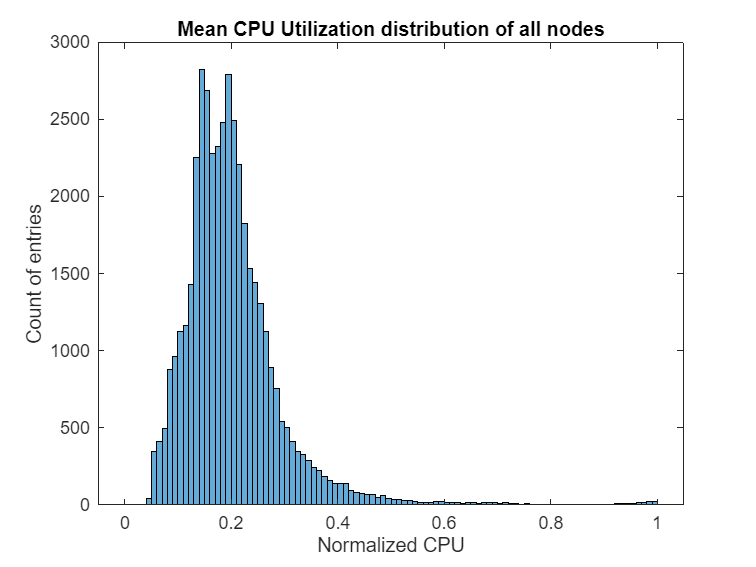

histogram(node_data.cpu_mean, 100);
title("Mean CPU Utilization distribution of all nodes");
ylabel("Count of entries");
xlabel("Normalized CPU");

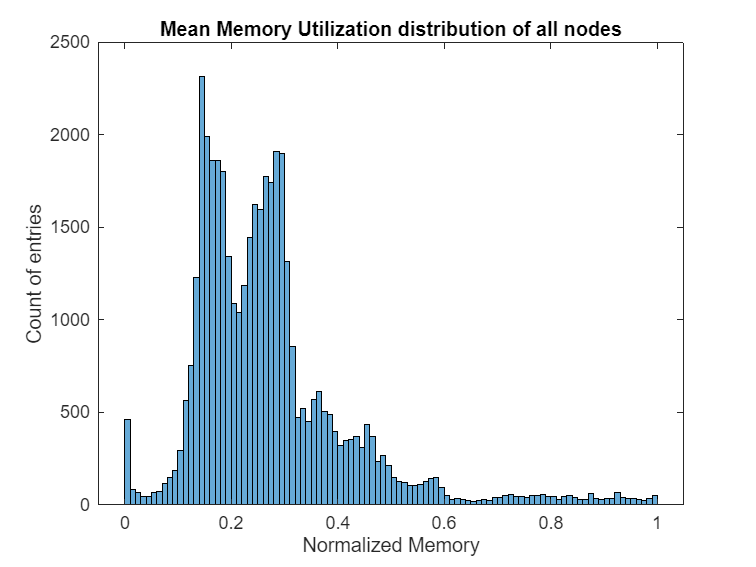

histogram(node_data.memory_mean, 100);
title("Mean Memory Utilization distribution of all nodes");
ylabel("Count of entries");
xlabel("Normalized Memory");

Get mean of mean

cpu_mean = (sum(node_data.cpu_count .* node_data.cpu_mean) / sum(node_data.cpu_count));
memory_mean = (sum(node_data.memory_count .* node_data.memory_mean) / sum(node_data.memory_count));
fprintf("Means >>>> CPU: %.4f | MEMORY: %.4f", cpu_mean, memory_mean);

Means >>>> CPU: 0.2006 | MEMORY: 0.2708

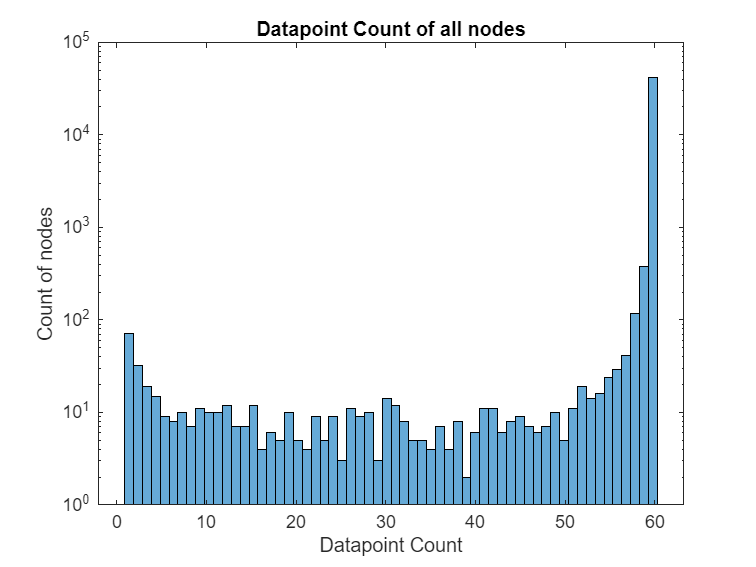

histogram(node_data.cpu_count, 60);
title("Datapoint Count of all nodes");
ylabel("Count of nodes");
yscale("log");
xlabel("Datapoint Count");

has_all_entries_idx = node_data.cpu_count == max_minutes;
fprintf("Percenteage of nodes with all metric entries: %.4f%", (sum(has_all_entries_idx) * 100 / node_count))

Percenteage of nodes with all metric entries: 97.3359

Nodes with missing metric entries show more extreme values, however they are only a small fraction of the data and can be left out.

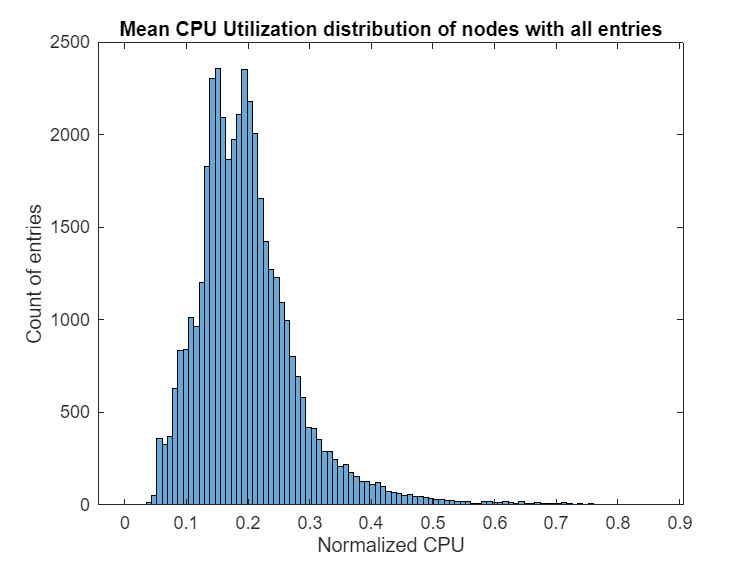

histogram(node_data.cpu_mean(has_all_entries_idx), 100);
title("Mean CPU Utilization distribution of nodes with all entries");
ylabel("Count of entries");
ylim([0 2500]);
xlabel("Normalized CPU");

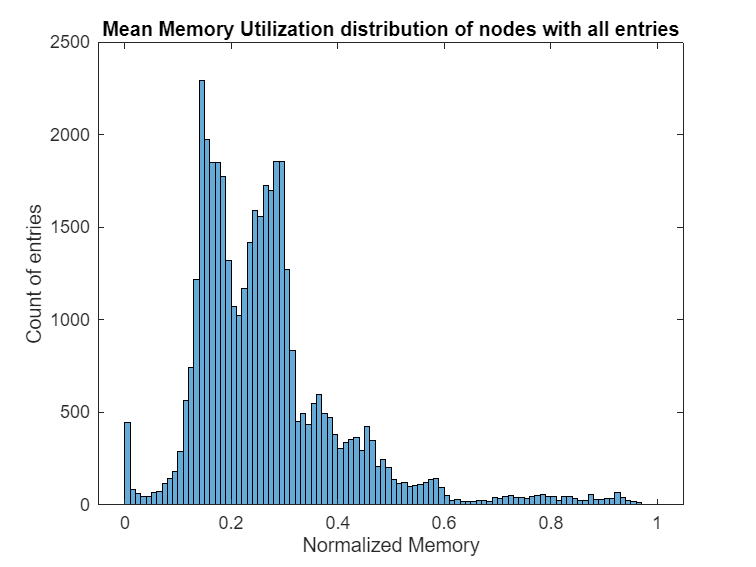

histogram(node_data.memory_mean(has_all_entries_idx), 100);
title("Mean Memory Utilization distribution of nodes with all entries");
ylabel("Count of entries");
ylim([0 2500]);
xlabel("Normalized Memory");

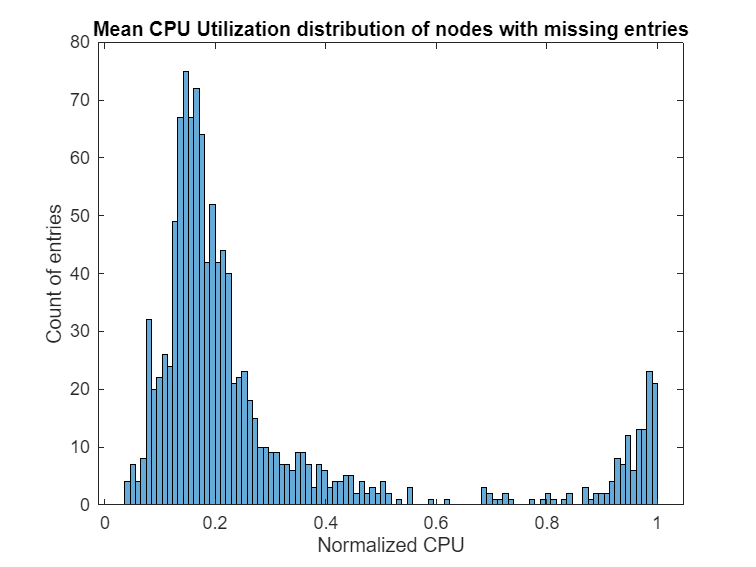


histogram(node_data.cpu_mean(~has_all_entries_idx), 100);
title("Mean CPU Utilization distribution of nodes with missing entries");
ylabel("Count of entries");
xlabel("Normalized CPU");

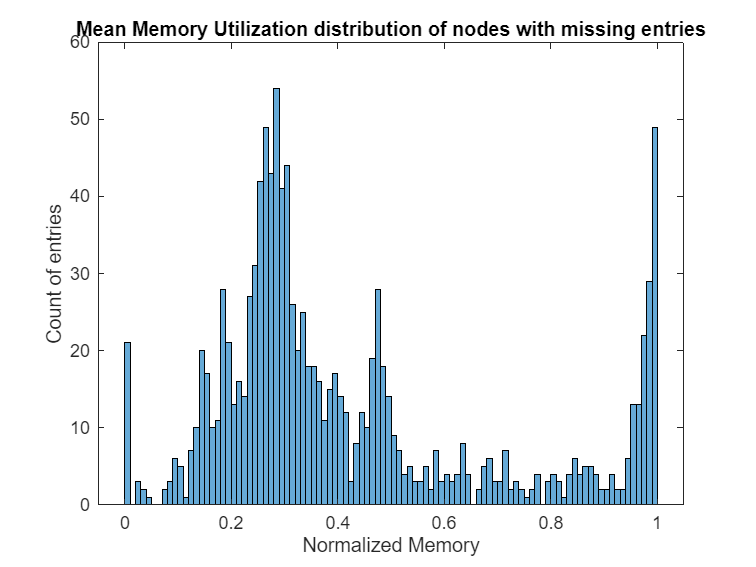

histogram(node_data.memory_mean(~has_all_entries_idx), 100);
title("Mean Memory Utilization distribution of nodes with missing entries");
ylabel("Count of entries");
xlabel("Normalized Memory");